w_ASDT = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/ASD_w_longitudinalv1_thresholded.mat');
ASDw = w_ASDT.tensor_ASDv1;
w_NTT = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/NT_w_longitudinalv1_thresholded.mat');
NTw = w_NTT.tensor_NTv1;
% ASDw = w_ASD_tensor(:,:,:,71);
% NTw = w_NT_tensor(:,:,:,71);

fc_ASDT = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/ASD_fc_longitudinalv1_thresholded.mat');
ASDfc = fc_ASDT.tensor_ASDv1;
fc_NTT = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/NT_fc_longitudinalv1_thresholded.mat');
NTfc = fc_NTT.tensor_NTv1;
% ASDfc = fc_ASD_tensor(:,:,:,66);
% NTfc = fc_NT_tensor(:,:,:,66);

%spot check
% nnz(ASDw(:,:,6))/(96^2)
% nnz(NTfc(:,:,10))/(96^2)
% 
% sum(diag(NTfc(:,:,8)))
% sum(diag(ASDw(:,:,16)))

ASD = [10001, 10002, 10003, 10004, 10005, 10008, 10010, 10020, 10021, 10050, 10059, 10061, 10069, 10077, 10079, 10090, 10091, 10092, 10093, 10096,...
    10101, 10115, 10119, 10124, 11001, 11003, 11007, 11014, 11019, 11031, 11038, 11044, 11054, 11059, 11061];
NT = [10009, 10013, 10014, 10015, 10016, 10017, 10019, 10036, 10044, 10052, 10057, 10076, 10086, 10088, 10103, 10106, 10112, 10113, 11006,...
    11008, 11009, 11013, 11016, 11021, 11027, 11028, 11032, 11039, 11041, 11074];

% beta1s_ASD_table = readtable('/Users/domo/Documents/MATLAB/Data/beta1s_ASD.xlsx');
% beta1s_NT_table = readtable('/Users/domo/Documents/MATLAB/Data/beta1s_NT.xlsx');
% 
% beta1s_ASD = table2array(beta1s_ASD_table);
% beta1s_NT = table2array(beta1s_NT_table);

RM96 = readtable('/Users/domo/Documents/MATLAB/Data/struct_matrices/over_sixty_thresholded/RM96_labels.xlsx');
consistency_w = 0:0.01:0.7;
consistency_fc = 0:0.01:0.65;

%global measures plotting color scheme
c = copper;
first_color_rgb = c(1,:); % Dark brown
last_color_rgb = c(end,:); % Light brown

SC_FC_ASD = zeros(length(ASD),96,length(consistency_fc));
deg_w_ASD = zeros(length(ASD),96,length(consistency_w));
str_w_ASD = zeros(length(ASD),96,length(consistency_w));
a_w_ASD = zeros(length(ASD),length(consistency_w));

cc_w_ASD = zeros(length(ASD),96,length(consistency_w));
trans_w_ASD = zeros(length(ASD),length(consistency_w));

charpath_w_ASD = zeros(length(ASD),length(consistency_w));
efficiency_w_ASD = zeros(length(ASD),length(consistency_w));
ecc_w_ASD = zeros(length(ASD),96,length(consistency_w));
rad_w_ASD = zeros(length(ASD),length(consistency_w));
diam_w_ASD = zeros(length(ASD),length(consistency_w));
bc_w_ASD = zeros(length(ASD),96,length(consistency_w));

mod_w_ASD = zeros(length(ASD),length(consistency_w));
cs_w_ASD = zeros(96,length(ASD),length(consistency_w));

swp_w_ASD = zeros(length(ASD),length(consistency_w));

deg_fc_ASD = zeros(length(ASD),96,length(consistency_fc));
str_fc_ASD = zeros(length(ASD),96,length(consistency_fc));
a_fc_ASD = zeros(length(ASD),length(consistency_fc));

cc_fc_ASD = zeros(length(ASD),96,length(consistency_fc));
trans_fc_ASD = zeros(length(ASD),length(consistency_fc));

charpath_fc_ASD = zeros(length(ASD),length(consistency_fc));
efficiency_fc_ASD = zeros(length(ASD),length(consistency_fc));
ecc_fc_ASD = zeros(length(ASD),96,length(consistency_fc));
rad_fc_ASD = zeros(length(ASD),length(consistency_fc));
diam_fc_ASD = zeros(length(ASD),length(consistency_fc));
bc_fc_ASD = zeros(length(ASD),96,length(consistency_fc));

mod_fc_ASD = zeros(length(ASD),length(consistency_fc));
cs_fc_ASD = zeros(96,length(ASD),length(consistency_fc));

swp_fc_ASD = zeros(length(ASD),length(consistency_fc));


% beta1s_filt_ASD = [];
% ASD_filt = [];
for j = 1:length(consistency_w)
    for i = 1:length(ASD)
        % if ismember(ASD(i),beta1s_ASD(:,1))
        %     ind = find(ASD(i)==beta1s_ASD(:,1));
        %     ASD_filt = [ASD_filt; ASD(i)];
        %     beta1s_filt_ASD = [beta1s_filt_ASD; beta1s_ASD(ind,:)];
    
            %individuals w and fc matrix
            w = ASDw(:,:,i,j);
            % fc = ASDfc(:,:,i,j);
    
            %structural classic measures
            deg_w = degrees_und(w);
            deg_w_ASD(i,:,j) = deg_w;
            str_w = strengths_und(w);
            str_w_ASD(i,:,j) = str_w;
            a_w = assortativity_wei(w,0);
            a_w_ASD(i,j) = a_w;
    
            [m_w,Q_w] = modularity_und(w);
            mod_w_ASD(i,j) = Q_w;
            cs_w_ASD(:,i,j) = m_w;
    
            w_nrm = weight_conversion(w,'normalize');
            cc_w = clustering_coef_wu(w_nrm);
            cc_w_ASD(i,:,j) = cc_w';
            trans_w = transitivity_wu(w_nrm);
            trans_w_ASD(i,j) = trans_w;
    
            L_w = weight_conversion(w,'lengths');
            bc_w = betweenness_wei(L_w);
            bc_w_ASD(i,:,j) = bc_w';
    
            [D_w, B_w] = distance_wei(L_w);
            [cp_w,eff_w,ecc_w,rad_w,diam_w] = charpath(D_w);
            charpath_w_ASD(i,j) = cp_w;
            efficiency_w_ASD(i,j) = eff_w;
            ecc_w_ASD(i,:,j) = ecc_w';
            rad_w_ASD(i,j) = rad_w;
            diam_w_ASD(i,j) = diam_w;
    
            %structural swp
            C_w_brain = mean(cc_w);
            Lp_w_brain = cp_w;
    
            W_rand = randomize_matrix(w);
            avg_degree_w = mean(degrees_und(w));
            r_w = ceil(avg_degree_w/2);
            W_latt = regular_matrix_generator(w,r_w);
    
            Wrand_nrm = weight_conversion(W_rand,'normalize');
            Wlatt_nrm = weight_conversion(W_latt,'normalize');
    
            cc_w_rand = clustering_coef_wu(Wrand_nrm);
            cc_w_latt = clustering_coef_wu(Wlatt_nrm);
            C_w_rand = mean(cc_w_rand);
            C_w_latt = mean(cc_w_latt);
    
            deltaC_w = (C_w_latt-C_w_brain)/(C_w_latt-C_w_rand);
    
            L_w_rand = weight_conversion(W_rand,'lengths');
            L_w_latt = weight_conversion(W_latt,'lengths');
            [D_w_rand, B_w_rand] = distance_wei(L_w_rand);
            [D_w_latt, B_w_latt] = distance_wei(L_w_latt);
            Lp_w_rand = charpath(D_w_rand);
            Lp_w_latt = charpath(D_w_latt);
        
            deltaL_w = (Lp_w_brain-Lp_w_rand)/(Lp_w_latt-Lp_w_rand);
        
            phi = 1 - sqrt((deltaC_w^2+deltaL_w^2)/2);
        
            swp_w_ASD(i,j) = phi;
    end
end


save('deg_w_ASD','deg_w_ASD')
save('str_w_ASD','str_w_ASD')
save('a_w_ASD','a_w_ASD')
save('cc_w_ASD','cc_w_ASD')
save('trans_w_ASD','trans_w_ASD')
save('charpath_w_ASD','charpath_w_ASD')
save('efficiency_w_ASD','efficiency_w_ASD')
save('ecc_w_ASD','ecc_w_ASD')
save('rad_w_ASD','rad_w_ASD')
save('diam_w_ASD','diam_w_ASD')
save('bc_w_ASD','bc_w_ASD')
save('mod_w_ASD','mod_w_ASD')
save('cs_w_ASD','cs_w_ASD')
save('swp_w_ASD','swp_w_ASD')

for j = 1:length(consistency_fc)
    for i = 1:length(ASD)

            w = ASDw(:,:,i,j);
            fc = ASDfc(:,:,i,j);

            %functional classic measures
            deg_fc = degrees_und(fc);
            deg_fc_ASD(i,:,j) = deg_fc;
            str_fc = strengths_und(fc);
            str_fc_ASD(i,:,j) = str_fc;
            a_fc = assortativity_wei(fc,0);
            a_fc_ASD(i,j) = a_fc;
    
            [m_fc,Q_fc] = modularity_und(fc);
            mod_fc_ASD(i,j) = Q_fc;
            cs_fc_ASD(:,i,j) = m_fc;
    
            fc_nrm = weight_conversion(fc,'normalize');
            cc_fc = clustering_coef_wu(fc_nrm);
            cc_fc_ASD(i,:,j) = cc_fc';
            trans_fc = transitivity_wu(fc_nrm);
            trans_fc_ASD(i,j) = trans_fc;
    
            L_fc = weight_conversion(fc,'lengths');
            bc_fc = betweenness_wei(L_fc);
            bc_fc_ASD(i,:,j) = bc_fc';
    
            [D_fc, B_fc] = distance_wei(L_fc);
            [cp_fc,eff_fc,ecc_fc,rad_fc,diam_fc] = charpath(D_fc);
            charpath_fc_ASD(i,j) = cp_fc;
            efficiency_fc_ASD(i,j) = eff_fc;
            ecc_fc_ASD(i,:,j) = ecc_fc';
            rad_fc_ASD(i,j) = rad_fc;
            diam_fc_ASD(i,j) = diam_fc;
    
            %funtional swp
            C_fc_brain = mean(cc_fc);
            Lp_fc_brain = cp_fc;
    
            FC_rand = randomize_matrix(fc);
            avg_degree_fc = mean(degrees_und(fc));
            r_fc = ceil(avg_degree_fc/2);
            FC_latt = regular_matrix_generator(fc,r_fc);
    
            FCrand_nrm = weight_conversion(FC_rand,'normalize');
            FClatt_nrm = weight_conversion(FC_latt,'normalize');
    
            cc_fc_rand = clustering_coef_wu(FCrand_nrm);
            cc_fc_latt = clustering_coef_wu(FClatt_nrm);
            C_fc_rand = mean(cc_fc_rand);
            C_fc_latt = mean(cc_fc_latt);
    
            deltaC_fc = (C_fc_latt-C_fc_brain)/(C_fc_latt-C_fc_rand);
    
            L_fc_rand = weight_conversion(FC_rand,'lengths');
            L_fc_latt = weight_conversion(FC_latt,'lengths');
            [D_fc_rand, B_fc_rand] = distance_wei(L_fc_rand);
            [D_fc_latt, B_fc_latt] = distance_wei(L_fc_latt);
            Lp_fc_rand = charpath(D_fc_rand);
            Lp_fc_latt = charpath(D_fc_latt);
        
            deltaL_fc = (Lp_fc_brain-Lp_fc_rand)/(Lp_fc_latt-Lp_fc_rand);
        
            phi = 1 - sqrt((deltaC_fc^2+deltaL_fc^2)/2);
        
            swp_fc_ASD(i,j) = phi;
    
            sc_fc = [];
            for k = 1:96
                rho = corr(w(:,k),fc(:,k),'Type','Spearman');
                sc_fc = [sc_fc, rho];
            end
            SC_FC_ASD(i,:,j) = sc_fc;
        % end
    end
end

save('SC_FC_ASD','SC_FC_ASD')
save('deg_fc_ASD','deg_fc_ASD')
save('str_fc_ASD','str_fc_ASD')
save('a_fc_ASD','a_fc_ASD')
save('cc_fc_ASD','cc_fc_ASD')
save('trans_fc_ASD','trans_fc_ASD')
save('charpath_fc_ASD','charpath_fc_ASD')
save('efficiency_fc_ASD','efficiency_fc_ASD')
save('ecc_fc_ASD','ecc_fc_ASD')
save('rad_fc_ASD','rad_fc_ASD')
save('diam_fc_ASD','diam_fc_ASD')
save('bc_fc_ASD','bc_fc_ASD')
save('mod_fc_ASD','mod_fc_ASD')
save('cs_fc_ASD','cs_fc_ASD')
save('swp_fc_ASD','swp_fc_ASD')

SC_FC_NT = zeros(length(NT),96,length(consistency_fc));
deg_w_NT = zeros(length(NT),96,length(consistency_w));
str_w_NT = zeros(length(NT),96,length(consistency_w));
a_w_NT = zeros(length(NT),length(consistency_w));

cc_w_NT = zeros(length(NT),96,length(consistency_w));
trans_w_NT = zeros(length(NT),length(consistency_w));

charpath_w_NT = zeros(length(NT),length(consistency_w));
efficiency_w_NT = zeros(length(NT),length(consistency_w));
ecc_w_NT = zeros(length(NT),96,length(consistency_w));
rad_w_NT = zeros(length(NT),length(consistency_w));
diam_w_NT = zeros(length(NT),length(consistency_w));
bc_w_NT = zeros(length(NT),96,length(consistency_w));

mod_w_NT = zeros(length(NT),length(consistency_w));
cs_w_NT = zeros(96,length(NT),length(consistency_w));

swp_w_NT = zeros(length(NT),length(consistency_w));

deg_fc_NT = zeros(length(NT),96,length(consistency_fc));
str_fc_NT = zeros(length(NT),96,length(consistency_fc));
a_fc_NT = zeros(length(NT),length(consistency_fc));

cc_fc_NT = zeros(length(NT),96,length(consistency_fc));
trans_fc_NT = zeros(length(NT),length(consistency_fc));

charpath_fc_NT = zeros(length(NT),length(consistency_fc));
efficiency_fc_NT = zeros(length(NT),length(consistency_fc));
ecc_fc_NT = zeros(length(NT),96,length(consistency_fc));
rad_fc_NT = zeros(length(NT),length(consistency_fc));
diam_fc_NT = zeros(length(NT),length(consistency_fc));
bc_fc_NT = zeros(length(NT),96,length(consistency_fc));

mod_fc_NT = zeros(length(NT),length(consistency_fc));
cs_fc_NT = zeros(96,length(NT),length(consistency_fc));

swp_fc_NT = zeros(length(NT),length(consistency_fc));

% beta1s_filt_NT = [];
% NT_filt = [];

for j = 1:length(consistency_w)
    for i = 1:length(NT)
        % if ismember(NT(i),beta1s_NT(:,1))
        %     ind = find(NT(i)==beta1s_NT(:,1));
        %     NT_filt = [NT_filt; NT(i)];
        %     beta1s_filt_NT = [beta1s_filt_NT; beta1s_NT(ind,:)];
    
            w = NTw(:,:,i,j);
            %fc = NTfc(:,:,i,j);
    
            deg_w = degrees_und(w);
            deg_w_NT(i,:,j) = deg_w;
            str_w = strengths_und(w);
            str_w_NT(i,:,j) = str_w;
            a_w = assortativity_wei(w,0);
            a_w_NT(i,j) = a_w;
    
            [m_w,Q_w] = modularity_und(w);
            mod_w_NT(i,j) = Q_w;
            cs_w_NT(:,i,j) = m_w;
    
            w_nrm = weight_conversion(w,'normalize');
            cc_w = clustering_coef_wu(w_nrm);
            cc_w_NT(i,:,j) = cc_w';
            trans_w = transitivity_wu(w_nrm);
            trans_w_NT(i,j) = trans_w;
    
            L_w = weight_conversion(w,'lengths');
            bc_w = betweenness_wei(L_w);
            bc_w_NT(i,:,j) = bc_w';
    
            [D_w, B_w] = distance_wei(L_w);
            [cp_w,eff_w,ecc_w,rad_w,diam_w] = charpath(D_w);
            charpath_w_NT(i,j) = cp_w;
            efficiency_w_NT(i,j) = eff_w;
            ecc_w_NT(i,:,j) = ecc_w';
            rad_w_NT(i,j) = rad_w;
            diam_w_NT(i,j) = diam_w;
    
            %structural swp
            C_w_brain = mean(cc_w);
            Lp_w_brain = cp_w;
    
            W_rand = randomize_matrix(w);
            avg_degree_w = mean(degrees_und(w));
            r_w = ceil(avg_degree_w/2);
            W_latt = regular_matrix_generator(w,r_w);
    
            Wrand_nrm = weight_conversion(W_rand,'normalize');
            Wlatt_nrm = weight_conversion(W_latt,'normalize');
    
            cc_w_rand = clustering_coef_wu(Wrand_nrm);
            cc_w_latt = clustering_coef_wu(Wlatt_nrm);
            C_w_rand = mean(cc_w_rand);
            C_w_latt = mean(cc_w_latt);
    
            deltaC_w = (C_w_latt-C_w_brain)/(C_w_latt-C_w_rand);
    
            L_w_rand = weight_conversion(W_rand,'lengths');
            L_w_latt = weight_conversion(W_latt,'lengths');
            [D_w_rand, B_w_rand] = distance_wei(L_w_rand);
            [D_w_latt, B_w_latt] = distance_wei(L_w_latt);
            Lp_w_rand = charpath(D_w_rand);
            Lp_w_latt = charpath(D_w_latt);
        
            deltaL_w = (Lp_w_brain-Lp_w_rand)/(Lp_w_latt-Lp_w_rand);
        
            phi = 1 - sqrt((deltaC_w^2+deltaL_w^2)/2);
        
            swp_w_NT(i,j) = phi;
    end
end

save('deg_w_NT','deg_w_NT')
save('str_w_NT','str_w_NT')
save('a_w_NT','a_w_NT')
save('cc_w_NT','cc_w_NT')
save('trans_w_NT','trans_w_NT')
save('charpath_w_NT','charpath_w_NT')
save('efficiency_w_NT','efficiency_w_NT')
save('ecc_w_NT','ecc_w_NT')
save('rad_w_NT','rad_w_NT')
save('diam_w_NT','diam_w_NT')
save('bc_w_NT','bc_w_NT')
save('mod_w_NT','mod_w_NT')
save('cs_w_NT','cs_w_NT')
save('swp_w_NT','swp_w_NT')

for j = 1:length(consistency_fc)
    for i = 1:length(NT)
            w = NTw(:,:,i,j);
            fc = NTfc(:,:,i,j);
            
            %functional classic measures
            deg_fc = degrees_und(fc);
            deg_fc_NT(i,:,j) = deg_fc;
            str_fc = strengths_und(fc);
            str_fc_NT(i,:,j) = str_fc;
            a_fc = assortativity_wei(fc,0);
            a_fc_NT(i,j) = a_fc;
    
            [m_fc,Q_fc] = modularity_und(fc);
            mod_fc_NT(i,j) = Q_fc;
            cs_fc_NT(:,i,j) = m_fc;
    
            fc_nrm = weight_conversion(fc,'normalize');
            cc_fc = clustering_coef_wu(fc_nrm);
            cc_fc_NT(i,:,j) = cc_fc';
            trans_fc = transitivity_wu(fc_nrm);
            trans_fc_NT(i,j) = trans_fc;
    
            L_fc = weight_conversion(fc,'lengths');
            bc_fc = betweenness_wei(L_fc);
            bc_fc_NT(i,:,j) = bc_fc';
    
            [D_fc, B_fc] = distance_wei(L_fc);
            [cp_fc,eff_fc,ecc_fc,rad_fc,diam_fc] = charpath(D_fc);
            charpath_fc_NT(i,j) = cp_fc;
            efficiency_fc_NT(i,j) = eff_fc;
            ecc_fc_NT(i,:,j) = ecc_fc';
            rad_fc_NT(i,j) = rad_fc;
            diam_fc_NT(i,j) = diam_fc;
    
            %funtional swp
            C_fc_brain = mean(cc_fc);
            Lp_fc_brain = cp_fc;
    
            FC_rand = randomize_matrix(fc);
            avg_degree_fc = mean(degrees_und(fc));
            r_fc = ceil(avg_degree_fc/2);
            FC_latt = regular_matrix_generator(fc,r_fc);
    
            FCrand_nrm = weight_conversion(FC_rand,'normalize');
            FClatt_nrm = weight_conversion(FC_latt,'normalize');
    
            cc_fc_rand = clustering_coef_wu(FCrand_nrm);
            cc_fc_latt = clustering_coef_wu(FClatt_nrm);
            C_fc_rand = mean(cc_fc_rand);
            C_fc_latt = mean(cc_fc_latt);
    
            deltaC_fc = (C_fc_latt-C_fc_brain)/(C_fc_latt-C_fc_rand);
    
            L_fc_rand = weight_conversion(FC_rand,'lengths');
            L_fc_latt = weight_conversion(FC_latt,'lengths');
            [D_fc_rand, B_fc_rand] = distance_wei(L_fc_rand);
            [D_fc_latt, B_fc_latt] = distance_wei(L_fc_latt);
            Lp_fc_rand = charpath(D_fc_rand);
            Lp_fc_latt = charpath(D_fc_latt);
        
            deltaL_fc = (Lp_fc_brain-Lp_fc_rand)/(Lp_fc_latt-Lp_fc_rand);
        
            phi = 1 - sqrt((deltaC_fc^2+deltaL_fc^2)/2);
        
            swp_fc_NT(i,j) = phi;
    
            sc_fc = [];
            for k = 1:96
                rho = corr(w(:,k),fc(:,k),'Type','Spearman');
                sc_fc = [sc_fc, rho];
            end
            SC_FC_NT(i,:,j) = sc_fc;
        % end
    end
end

save('SC_FC_NT','SC_FC_NT')
save('deg_fc_NT','deg_fc_NT')
save('str_fc_NT','str_fc_NT')
save('a_fc_NT','a_fc_NT')
save('cc_fc_NT','cc_fc_NT')
save('trans_fc_NT','trans_fc_NT')
save('charpath_fc_NT','charpath_fc_NT')
save('efficiency_fc_NT','efficiency_fc_NT')
save('ecc_fc_NT','ecc_fc_NT')
save('rad_fc_NT','rad_fc_NT')
save('diam_fc_NT','diam_fc_NT')
save('bc_fc_NT','bc_fc_NT')
save('mod_fc_NT','mod_fc_NT')
save('cs_fc_NT','cs_fc_NT')
save('swp_fc_NT','swp_fc_NT')

%%functional BY fdr correction
load('bc_fc_ASD.mat')
load('bc_fc_NT.mat')
p_fc_bc = zeros(96,length(consistency_fc));
od_fc_bc = zeros(96,length(consistency_fc));
es_fc_bc = zeros(96,length(consistency_fc));
for j = 1:length(consistency_fc)
    for i = 1:96
        [p_bci, od_bci, es_bci] = permutationTest(bc_fc_NT(:,i,j),bc_fc_ASD(:,i,j),10000);
        p_fc_bc(i,j) = p_bci;
        od_fc_bc(i,j) = od_bci;
        es_fc_bc(i,j) = es_bci;
    end
end
save('p_fc_bc','p_fc_bc')

load('cc_fc_ASD.mat')
load('cc_fc_NT.mat')
p_fc_cc = zeros(96,length(consistency_fc));
od_fc_cc = zeros(96,length(consistency_fc));
es_fc_cc = zeros(96,length(consistency_fc));
for j = 1:length(consistency_fc)
    for i = 1:96
        [p_cci, od_cci, es_cci] = permutationTest(cc_fc_NT(:,i,j),cc_fc_ASD(:,i,j),10000);
        p_fc_cc(i,j) = p_cci;
        od_fc_cc(i,j) = od_cci;
        es_fc_cc(i,j) = es_cci;
    end
end
save('p_fc_cc','p_fc_cc')

load('ecc_fc_ASD.mat')
load('ecc_fc_NT.mat')
p_fc_ecc = zeros(96,length(consistency_fc));
od_fc_ecc = zeros(96,length(consistency_fc));
es_fc_ecc = zeros(96,length(consistency_fc));
for j = 1:length(consistency_fc)
    for i = 1:96
        [p_ecci, od_ecci, es_ecci] = permutationTest(ecc_fc_NT(:,i,j),ecc_fc_ASD(:,i,j),10000);
        p_fc_ecc(i,j) = p_ecci;
        od_fc_ecc(i,j) = od_ecci;
        es_fc_ecc(i,j) = es_ecci;
    end
end
save('p_fc_ecc','p_fc_ecc')

load('deg_fc_ASD.mat')
load('deg_fc_NT.mat')
p_fc_deg = zeros(96,length(consistency_fc));
od_fc_deg = zeros(96,length(consistency_fc));
es_fc_deg = zeros(96,length(consistency_fc));
for j = 1:length(consistency_fc)
    for i = 1:96
        [p_degi, od_degi, es_degi] = permutationTest(deg_fc_NT(:,i,j),deg_fc_ASD(:,i,j),10000);
        p_fc_deg(i,j) = p_degi;
        od_fc_deg(i,j) = od_degi;
        es_fc_deg(i,j) = es_degi;
    end
end
save('p_fc_deg','p_fc_deg')

load('str_fc_ASD.mat')
load('str_fc_NT.mat')
p_fc_str = zeros(96,length(consistency_fc));
od_fc_str = zeros(96,length(consistency_fc));
es_fc_str = zeros(96,length(consistency_fc));
for j = 1:length(consistency_fc)
    for i = 1:96
        [p_stri, od_stri, es_stri] = permutationTest(str_fc_NT(:,i,j),str_fc_ASD(:,i,j),10000);
        p_fc_str(i,j) = p_stri;
        od_fc_str(i,j) = od_stri;
        es_fc_str(i,j) = es_stri;
    end
end
save('p_fc_str','p_fc_str')

load('cs_fc_ASD.mat')
load('cs_fc_NT.mat')
%difference in assignment of different nodes
p_fc_cs = zeros(96,length(consistency_fc));
for m = 1:length(consistency_fc)
    for i = 1:96
        bin_ASD = zeros(96,length(ASD));
        bin_NT = zeros(96,length(NT));
        for j = 1:length(ASD)
            label = cs_fc_ASD(i,j,m);
            bin_ASD(:,j) = cs_fc_ASD(:,j,m)==label;
        end
        for k = 1:length(NT)
            label = cs_fc_NT(i,k,m);
            bin_NT(:,k) = cs_fc_NT(:,k,m)==label;
        end
        R_ASD = corrcoef(bin_ASD);
        R_NT = corrcoef(bin_NT);
        R_od = mean(R_ASD,'all')+mean(R_NT,'all');
        randomdifferences = zeros(1,10000);
        for l = 1:10000
            allobservations = [bin_ASD,bin_NT];
            permtuation = randperm(size(allobservations,2));
            randSample1 = allobservations(:,permtuation(1:length(ASD)));
            randSample2 = allobservations(:,permtuation(length(ASD)+1:length(permtuation)));
            R_S1 = corrcoef(randSample1);
            R_S2 = corrcoef(randSample2);
            randomdifferences(l) = mean(R_S1,'all')+mean(R_S2,'all');
        end
        p_fc_cs(i,m) = (length(find(abs(randomdifferences)>abs(R_od)))+1)/(10000+1);
    end
end
save('p_fc_cs','p_fc_cs')

load('p_fc_bc.mat')
load('p_fc_cc.mat')
load('p_fc_ecc.mat')
load('p_fc_deg.mat')
load('p_fc_str.mat')
load('p_fc_cs.mat')
%need to correct that the first two columns for p-values reflect no
%significant difference

p_fc_deg(:,1:2)=1;

p_fc_deg =     1.0000    1.0000    0.7071    0.5091    0.4808    0.4636    0.4406    0.8732    0.7221    0.6208    0.6448    0.6245    0.8007    0.4592    0.1818    0.1189    0.1549    0.2339    0.3255    0.2330    0.1875    0.1979    0.1846    0.2288    0.3457    0.4365    0.4942    0.6389    0.8076    0.8112    0.8329    0.8220    0.8822    0.8628    0.9181    0.9887    0.9368    0.8595    0.7048    0.7262    0.8882    0.8576    0.8599    0.9159    0.8447    0.9446    0.9581    0.9361    0.9404    0.8283
    1.0000    1.0000    0.2469    0.0377    0.1416    0.0731    0.1274    0.0416    0.0244    0.0146    0.0185    0.0255    0.0728    0.0549    0.1520    0.3051    0.3303    0.3005    0.3214    0.3653    0.4980    0.3685    0.2278    0.2572    0.2064    0.2051    0.1313    0.1365    0.0531    0.0694    0.0747    0.0663    0.0503    0.0372    0.0281    0.0148    0.0109    0.0148    0.0152    0.0131    0.0142    0.0110    0.0108    0.0098    0.0067    0.0078    0.0064    0.0079    0.00


p_fc_fdr_nodes = zeros(96,6,length(consistency_fc));
for j = 1:length(consistency_fc)
    for i = 1:96
        p_group = [p_fc_bc(i,j), p_fc_cc(i,j), p_fc_ecc(i,j), p_fc_deg(i,j), p_fc_str(i,j), p_fc_cs(i,j)];
        [h, crit_p, adj_ci_cvrg, adj_p]=fdr_bh(p_group,0.05,'dep');
        p_fc_fdr_nodes(i,:,j) = adj_p;
    end
end
save('p_fc_fdr_nodes','p_fc_fdr_nodes')

load('a_fc_ASD.mat')
load('a_fc_NT.mat')
load('trans_fc_ASD.mat')
load('trans_fc_NT.mat')
load('charpath_fc_ASD.mat')
load('charpath_fc_NT.mat')
load('efficiency_fc_ASD.mat')
load('efficiency_fc_NT.mat')
load('diam_fc_ASD.mat')
load('diam_fc_NT.mat')
load('rad_fc_ASD.mat')
load('rad_fc_NT.mat')
load('mod_fc_ASD.mat')
load('mod_fc_NT.mat')
load('swp_fc_ASD.mat')
load('swp_fc_NT.mat')
load('cs_fc_ASD.mat')
load('cs_fc_NT.mat')
p_fc_glob = zeros(9,length(consistency_fc));
for j = 1:length(consistency_fc)
    [p_fc_assort, od_fc_assort, es_fc_assort] = permutationTest(a_fc_NT(:,j),a_fc_ASD(:,j),10000);
    [p_fc_tran, od_fc_tran, es_fc_tran] = permutationTest(trans_fc_NT(:,j),trans_fc_ASD(:,j),10000);
    [p_fc_cp, od_fc_cp, es_fc_cp] = permutationTest(charpath_fc_NT(:,j),charpath_fc_ASD(:,j),10000);
    [p_fc_diam, od_fc_diam, es_fc_diam] = permutationTest(diam_fc_NT(:,j),diam_fc_ASD(:,j),10000);
    [p_fc_rad, od_fc_rad, es_fc_rad] = permutationTest(rad_fc_NT(:,j),rad_fc_ASD(:,j),10000);
    [p_fc_eff, od_fc_eff, es_fc_eff] = permutationTest(efficiency_fc_NT(:,j),efficiency_fc_ASD(:,j),10000);
    [p_fc_mod, od_fc_mod, es_fc_mod] = permutationTest(mod_fc_NT(:,j),mod_fc_ASD(:,j),10000);
    [p_fc_swp, od_fc_swp, es_fc_swp] = permutationTest(swp_fc_NT(:,j),swp_fc_ASD(:,j),10000);

    [viASD, miASD] = partition_distance(cs_fc_ASD(:,:,j));
    [viNT, miNT] = partition_distance(cs_fc_NT(:,:,j));
    within_ASD = mean(miASD,'all');
    within_NT = mean(miNT,'all');
    tot_mni = within_ASD+within_NT;
    % mi_od = mean(miASD,'all')-mean(miNT,'all');
    randomdifferences = zeros(1,10000);
    for i = 1:10000
        allobservations = [cs_fc_ASD,cs_fc_NT];
        permtuation = randperm(size(allobservations,2));
        randSample1 = allobservations(:,permtuation(1:length(ASD)));
        randSample2 = allobservations(:,permtuation(length(ASD)+1:length(permtuation)));
        [viS1, miS1] = partition_distance(randSample1);
        [viS2, miS2] = partition_distance(randSample2);
        randomdifferences(i) = mean(miS1,'all')+mean(miS2,'all');
    end
    p_fc_globcs = (length(find(abs(randomdifferences)>abs(tot_mni)))+1)/(10000+1);
    
    p_fc_glob(:,j) = [p_fc_assort;p_fc_tran;p_fc_cp;p_fc_eff;p_fc_diam;p_fc_rad;p_fc_mod;p_fc_swp;p_fc_globcs];
end

save('p_fc_glob','p_fc_glob')

load('p_fc_glob.mat')
p_fc_glob_fdr = zeros(9,length(consistency_fc));
for j = 1:length(consistency_fc)
    [h_fc_glob, crit_p_fc_glob, adj_ci_cvrg_fc_glob, p_fc_glob_adj]=fdr_bh(p_fc_glob(:,j),0.05,'dep');
    p_fc_glob_fdr(:,j) = p_fc_glob_adj;
end
save('p_fc_glob_fdr','p_fc_glob_fdr')

%%structural BY fdr correction
load('bc_w_ASD.mat')
load('bc_w_NT.mat')
p_w_bc = zeros(96,length(consistency_w));
od_w_bc = zeros(96,length(consistency_w));
es_w_bc = zeros(96,length(consistency_w));
for j = 1:length(consistency_w)
    for i = 1:96
        [p_bci, od_bci, es_bci] = permutationTest(bc_w_NT(:,i,j),bc_w_ASD(:,i,j),10000);
        p_w_bc(i,j) = p_bci;
        od_w_bc(i,j) = od_bci;
        es_w_bc(i,j) = es_bci;
    end
end
save('p_w_bc','p_w_bc')

load('cc_w_ASD.mat')
load('cc_w_NT.mat')
p_w_cc = zeros(96,length(consistency_w));
od_w_cc = zeros(96,length(consistency_w));
es_w_cc = zeros(96,length(consistency_w));
for j = 1:length(consistency_w)
    for i = 1:96
        [p_cci, od_cci, es_cci] = permutationTest(cc_w_NT(:,i,j),cc_w_ASD(:,i,j),10000);
        p_w_cc(i,j) = p_cci;
        od_w_cc(i,j) = od_cci;
        es_w_cc(i,j) = es_cci;
    end
end
save('p_w_cc','p_w_cc')

load('ecc_w_ASD.mat')
load('ecc_w_NT.mat')
p_w_ecc = zeros(96,length(consistency_w));
od_w_ecc = zeros(96,length(consistency_w));
es_w_ecc = zeros(96,length(consistency_w));
for j = 1:length(consistency_w)
    for i = 1:96
        [p_ecci, od_ecci, es_ecci] = permutationTest(ecc_w_NT(:,i,j),ecc_w_ASD(:,i,j),10000);
        p_w_ecc(i,j) = p_ecci;
        od_w_ecc(i,j) = od_ecci;
        es_w_ecc(i,j) = es_ecci;
    end
end
save('p_w_ecc','p_w_ecc')

load('deg_w_ASD.mat')
load('deg_w_NT.mat')
p_w_deg = zeros(96,length(consistency_w));
od_w_deg = zeros(96,length(consistency_w));
es_w_deg = zeros(96,length(consistency_w));
for j = 1:length(consistency_w)
    for i = 1:96
        [p_degi, od_degi, es_degi] = permutationTest(deg_w_NT(:,i,j),deg_w_ASD(:,i,j),10000);
        p_w_deg(i,j) = p_degi;
        od_w_deg(i,j) = od_degi;
        es_w_deg(i,j) = es_degi;
    end
end
save('p_w_deg','p_w_deg')

load('str_w_ASD.mat')
load('str_w_NT.mat')
p_w_str = zeros(96,length(consistency_w));
od_w_str = zeros(96,length(consistency_w));
es_w_str = zeros(96,length(consistency_w));
for j = 1:length(consistency_w)
    for i = 1:96
        [p_stri, od_stri, es_stri] = permutationTest(str_w_NT(:,i,j),str_w_ASD(:,i,j),10000);
        p_w_str(i,j) = p_stri;
        od_w_str(i,j) = od_stri;
        es_w_str(i,j) = es_stri;
    end
end
save('p_w_str','p_w_str')

load('cs_w_ASD.mat')
load('cs_w_NT.mat')
%difference in assignment of different nodes
p_w_cs = zeros(96,length(consistency_w));
for m = 1:length(consistency_w)
    for i = 1:96
        bin_ASD = zeros(96,length(ASD));
        bin_NT = zeros(96,length(NT));
        for j = 1:length(ASD)
            label = cs_w_ASD(i,j,m);
            bin_ASD(:,j) = cs_w_ASD(:,j,m)==label;
        end
        for k = 1:length(NT)
            label = cs_w_NT(i,k,m);
            bin_NT(:,k) = cs_w_NT(:,k,m)==label;
        end
        R_ASD = corrcoef(bin_ASD);
        R_NT = corrcoef(bin_NT);
        R_od = mean(R_ASD,'all')+mean(R_NT,'all');
        randomdifferences = zeros(1,10000);
        for l = 1:10000
            allobservations = [bin_ASD,bin_NT];
            permtuation = randperm(size(allobservations,2));
            randSample1 = allobservations(:,permtuation(1:length(ASD)));
            randSample2 = allobservations(:,permtuation(length(ASD)+1:length(permtuation)));
            R_S1 = corrcoef(randSample1);
            R_S2 = corrcoef(randSample2);
            randomdifferences(l) = mean(R_S1,'all')+mean(R_S2,'all');
        end
        p_w_cs(i,m) = (length(find(abs(randomdifferences)>abs(R_od)))+1)/(10000+1);
    end
end
save('p_w_cs','p_w_cs')

load('p_w_bc.mat')
load('p_w_cc.mat')
load('p_w_ecc.mat')
load('p_w_deg.mat')
load('p_w_str.mat')
load('p_w_cs.mat')
p_w_fdr_nodes = zeros(96,6,length(consistency_w));
for j = 1:length(consistency_w)
    for i = 1:96
        p_group = [p_w_bc(i,j), p_w_cc(i,j), p_w_ecc(i,j), p_w_deg(i,j), p_w_str(i,j), p_w_cs(i,j)];
        [h, crit_p, adj_ci_cvrg, adj_p]=fdr_bh(p_group,0.05,'dep');
        p_w_fdr_nodes(i,:,j) = adj_p;
    end
end
save('p_w_fdr_nodes','p_w_fdr_nodes')

load('a_w_ASD.mat')
load('a_w_NT.mat')
load('trans_w_ASD.mat')
load('trans_w_NT.mat')
load('charpath_w_ASD.mat')
load('charpath_w_NT.mat')
load('efficiency_w_ASD.mat')
load('efficiency_w_NT.mat')
load('diam_w_ASD.mat')
load('diam_w_NT.mat')
load('rad_w_ASD.mat')
load('rad_w_NT.mat')
load('mod_w_ASD.mat')
load('mod_w_NT.mat')
load('swp_w_ASD.mat')
load('swp_w_NT.mat')
load('cs_w_ASD.mat')
load('cs_w_NT.mat')
p_w_glob = zeros(9,length(consistency_w));
for j = 1:length(consistency_w)
    [p_w_assort, od_w_assort, es_w_assort] = permutationTest(a_w_NT(:,j),a_w_ASD(:,j),10000);
    [p_w_tran, od_w_tran, es_w_tran] = permutationTest(trans_w_NT(:,j),trans_w_ASD(:,j),10000);
    [p_w_cp, od_w_cp, es_w_cp] = permutationTest(charpath_w_NT(:,j),charpath_w_ASD(:,j),10000);
    [p_w_diam, od_w_diam, es_w_diam] = permutationTest(diam_w_NT(:,j),diam_w_ASD(:,j),10000);
    [p_w_rad, od_w_rad, es_w_rad] = permutationTest(rad_w_NT(:,j),rad_w_ASD(:,j),10000);
    [p_w_eff, od_w_eff, es_w_eff] = permutationTest(efficiency_w_NT(:,j),efficiency_w_ASD(:,j),10000);
    [p_w_mod, od_w_mod, es_w_mod] = permutationTest(mod_w_NT(:,j),mod_w_ASD(:,j),10000);
    [p_w_swp, od_w_swp, es_w_swp] = permutationTest(swp_w_NT(:,j),swp_w_ASD(:,j),10000);

    [viASD, miASD] = partition_distance(cs_w_ASD(:,:,j));
    [viNT, miNT] = partition_distance(cs_w_NT(:,:,j));
    within_ASD = mean(miASD,'all');
    within_NT = mean(miNT,'all');
    tot_mni = within_ASD+within_NT;
    % mi_od = mean(miASD,'all')-mean(miNT,'all');
    randomdifferences = zeros(1,10000);
    for i = 1:10000
        allobservations = [cs_w_ASD,cs_w_NT];
        permtuation = randperm(size(allobservations,2));
        randSample1 = allobservations(:,permtuation(1:length(ASD)));
        randSample2 = allobservations(:,permtuation(length(ASD)+1:length(permtuation)));
        [viS1, miS1] = partition_distance(randSample1);
        [viS2, miS2] = partition_distance(randSample2);
        randomdifferences(i) = mean(miS1,'all')+mean(miS2,'all');
    end
    p_w_globcs = (length(find(abs(randomdifferences)>abs(tot_mni)))+1)/(10000+1);
    
    p_w_glob(:,j) = [p_w_assort;p_w_tran;p_w_cp;p_w_eff;p_w_diam;p_w_rad;p_w_mod;p_w_swp;p_w_globcs];
end

save('p_w_glob','p_w_glob')

load('p_w_glob.mat')
p_w_glob_fdr = zeros(9,length(consistency_w));
for j = 1:length(consistency_w)
    [h_w_glob, crit_p_w_glob, adj_ci_cvrg_w_glob, p_w_glob_adj]=fdr_bh(p_w_glob(:,j),0.05,'dep');
    p_w_glob_fdr(:,j) = p_w_glob_adj;
end
save('p_w_glob_fdr','p_w_glob_fdr')

%%SC-FC
load('sc_fc_ASD.mat')
load('sc_fc_NT.mat')
p_scfc = zeros(96,length(consistency_fc));
od_scfc = zeros(96,length(consistency_fc));
es_scfc = zeros(96,length(consistency_fc));
for j = 1:length(consistency_fc)
    for i = 1:96
        [p_scfci, od_scfci, es_scfci] = permutationTest(SC_FC_NT(:,i,j),SC_FC_ASD(:,i,j),10000);
        p_scfc(i,j) = p_scfci;
        od_scfc(i,j) = od_scfci;
        es_scfc(i,j) = es_scfci;
    end
end
save('p_scfc','p_scfc')

## Plotting Significance Across Thresholds

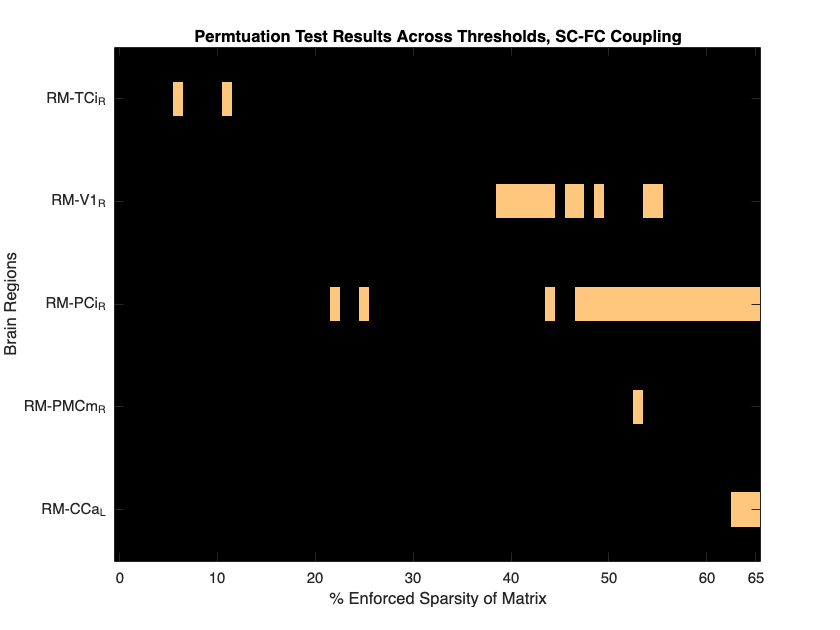

%SC-FC coupling
load('p_scfc.mat')
bT_scfc = p_scfc<0.01;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_scfc(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end

figure;
imagesc(bT_scfc(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.01';'p<0.01'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Permtuation Test Results Across Thresholds, SC-FC Coupling')

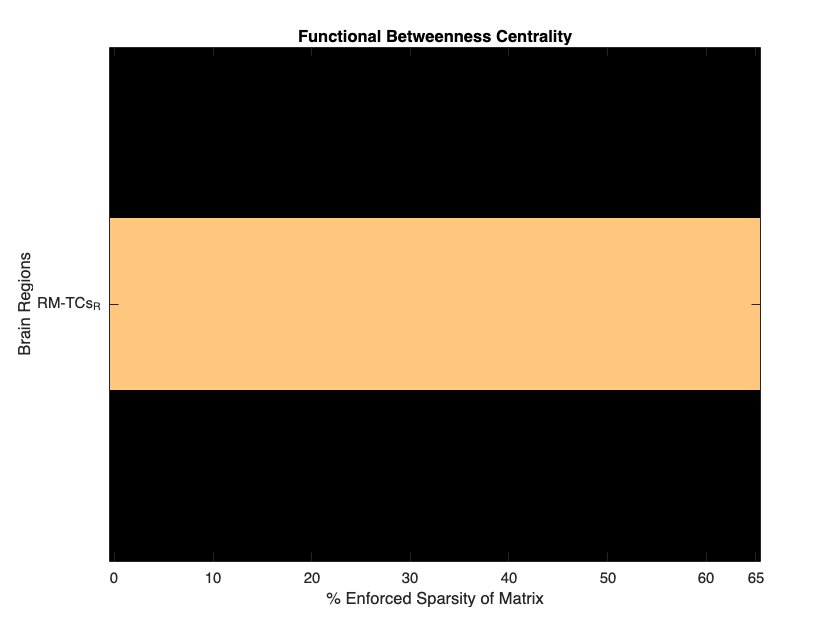

%Functional betweenness centrality
load('p_fc_fdr_nodes.mat')
p_fc_bc = squeeze(p_fc_fdr_nodes(:,1,:));
bT_fc_bc = p_fc_bc<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_fc_bc(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_fc_bc(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Functional Betweenness Centrality')

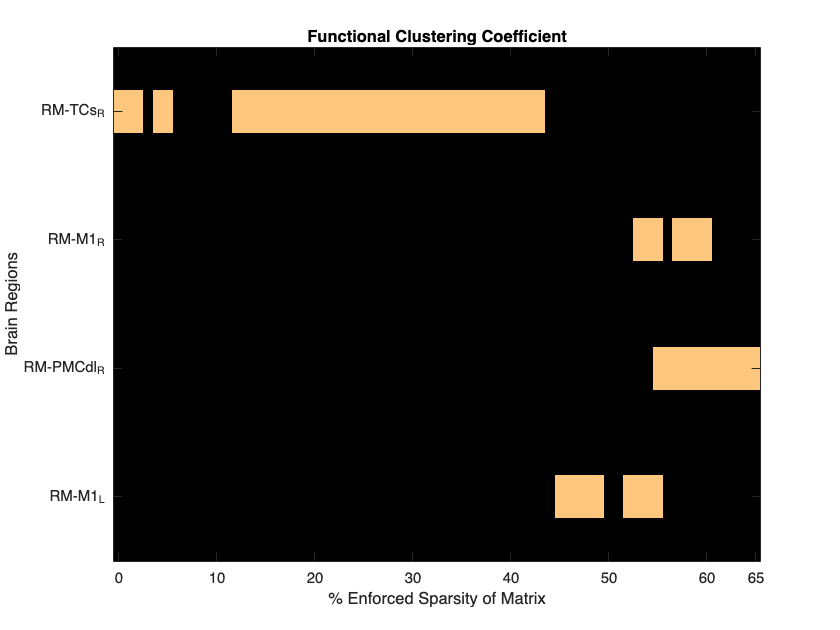

%Functional clustering coefficient
load('p_fc_fdr_nodes.mat')
p_fc_cc = squeeze(p_fc_fdr_nodes(:,2,:));
bT_fc_cc = p_fc_cc<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_fc_cc(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end

figure;
imagesc(bT_fc_cc(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Functional Clustering Coefficient')

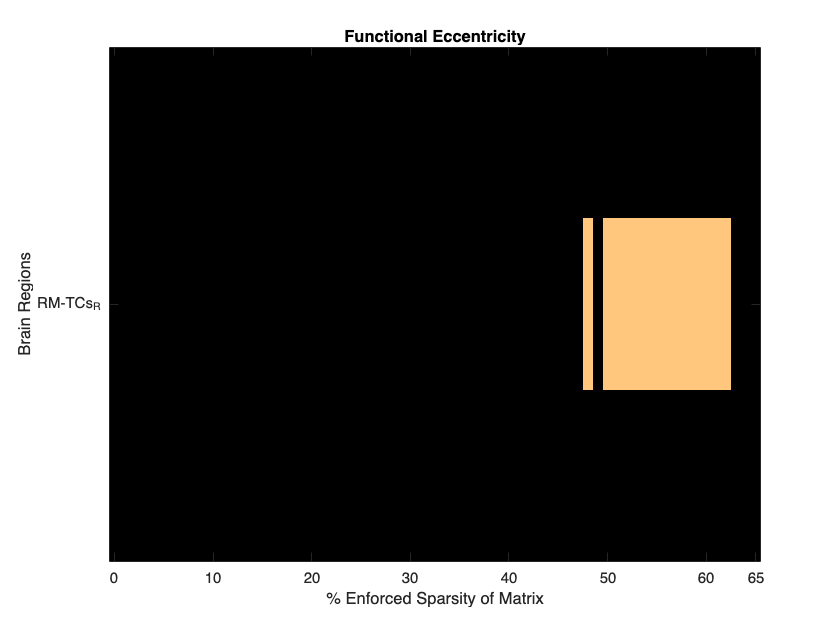

%Functional eccentricity
load('p_fc_fdr_nodes.mat')
p_fc_ecc = squeeze(p_fc_fdr_nodes(:,3,:));
bT_fc_ecc = p_fc_ecc<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_fc_ecc(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_fc_ecc(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Functional Eccentricity')

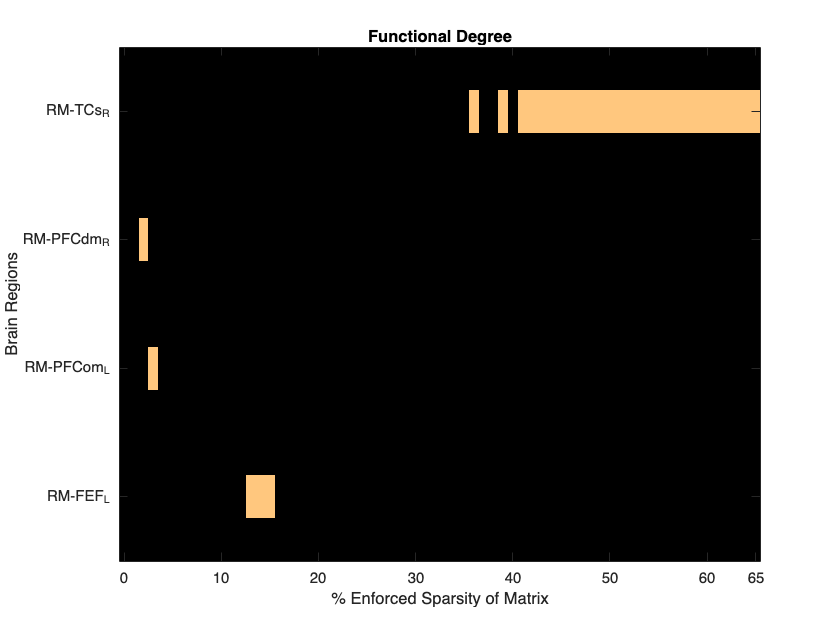

%Functional Degree
load('p_fc_fdr_nodes.mat')
p_fc_deg = squeeze(p_fc_fdr_nodes(:,4,:));
bT_fc_deg = p_fc_deg<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_fc_deg(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_fc_deg(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Functional Degree')

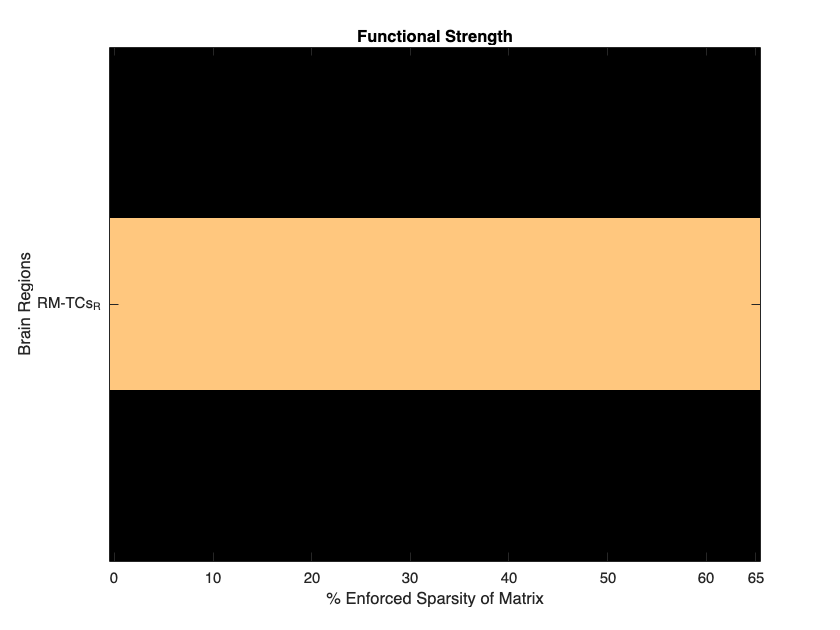

%Functional strength
load('p_fc_fdr_nodes.mat')
p_fc_str = squeeze(p_fc_fdr_nodes(:,5,:));
bT_fc_str = p_fc_str<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_fc_str(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_fc_str(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Functional Strength')

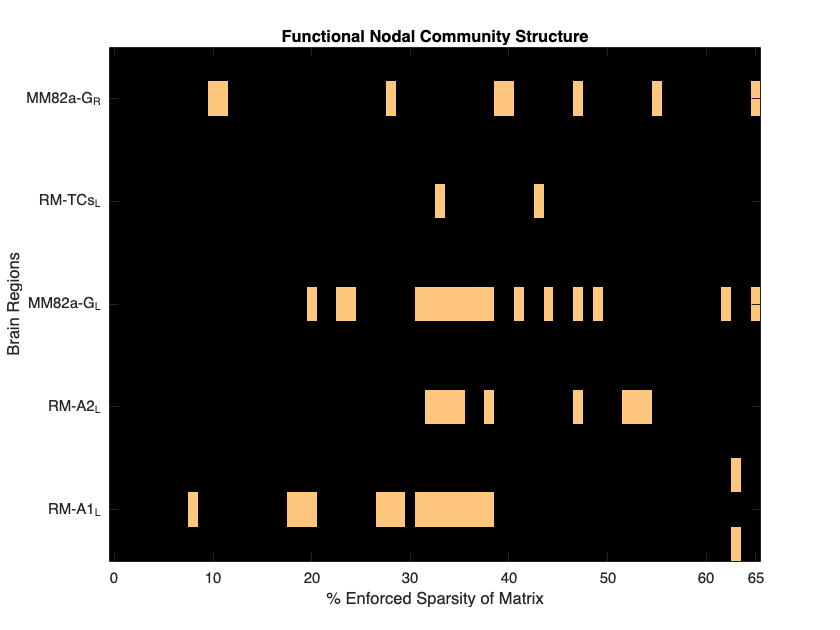

%Functional Community Structure Assignment
load('p_fc_fdr_nodes.mat')
p_fc_cs = squeeze(p_fc_fdr_nodes(:,6,:));
bT_fc_cs = p_fc_cs<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_fc_cs(i,:))>1
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_fc_cs(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Functional Nodal Community Structure')

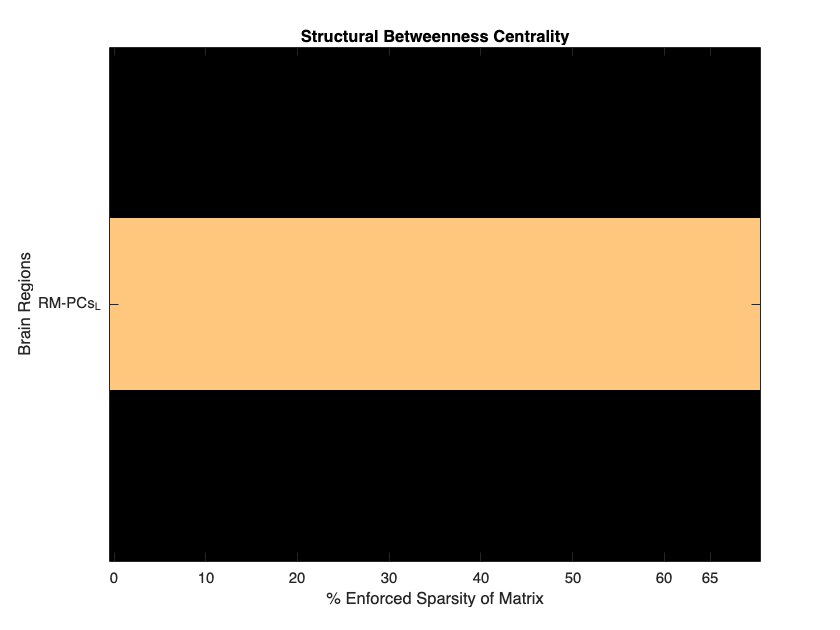

%Structural betweenness centrality
load('p_w_fdr_nodes.mat')
p_w_bc = squeeze(p_w_fdr_nodes(:,1,:));
bT_w_bc = p_w_bc<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_w_bc(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_w_bc(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Structural Betweenness Centrality')

%Structural clustering coefficient
load('p_w_fdr_nodes.mat')
p_w_cc = squeeze(p_w_fdr_nodes(:,2,:));
bT_w_cc = p_w_cc<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_w_cc(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end

Index exceeds array bounds.

figure;
imagesc(bT_w_cc(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Structural Clustering Coefficient')

%Structural eccentricity
load('p_w_fdr_nodes.mat')
p_w_ecc = squeeze(p_w_fdr_nodes(:,3,:));
bT_w_ecc = p_w_ecc<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_w_ecc(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end

Index exceeds array bounds.

figure;
imagesc(bT_w_ecc(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Structural Eccentricity')

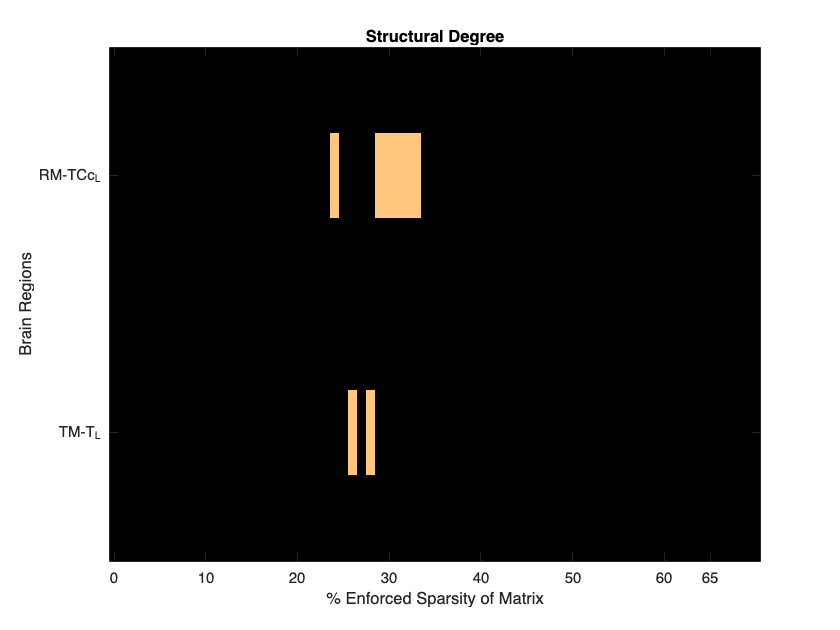

%Structural Degree
load('p_w_fdr_nodes.mat')
p_w_deg = squeeze(p_w_fdr_nodes(:,4,:));
bT_w_deg = p_w_deg<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_w_deg(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_w_deg(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Structural Degree')

%Structural strength
load('p_w_fdr_nodes.mat')
p_w_str = squeeze(p_w_fdr_nodes(:,5,:));
bT_w_str = p_w_str<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_w_str(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end

Index exceeds array bounds.

figure;
imagesc(bT_w_str(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Structural Strength')

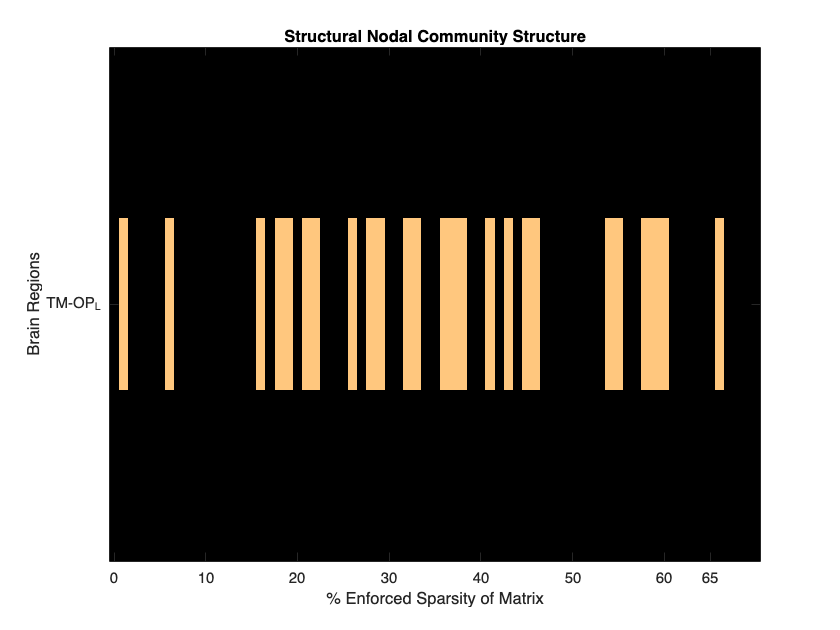

%Structural Community Structure Assignment
load('p_w_fdr_nodes.mat')
p_w_cs = squeeze(p_w_fdr_nodes(:,6,:));
bT_w_cs = p_w_cs<0.05;
yts = [];
ylabs = [];
ylabels = [];
for i = 1:96
    if sum(bT_w_cs(i,:))~=0
        if i==1
            yts = [yts, i, i+1];
        else 
            yts = [yts, i-1, i, i+1];
            ylabels = [ylabels, RM96{i,'Labels'}];
        end
    end
end
if isequal(ylabels(1),RM96{1,'Labels'})
    ylabs = [1, 4:3:length(yts)];
else
    ylabs = [2:3:length(yts)];
end
figure;
imagesc(bT_w_cs(yts,:))
colormap('copper')
% cbh = colorbar;
% cbh.Ticks = [0,1];
% cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,66])
xticklabels([0,10,20,30,40,50,60,65])
ylabel('Brain Regions')
yticks(ylabs)
yticklabels(ylabels)
title('Structural Nodal Community Structure')

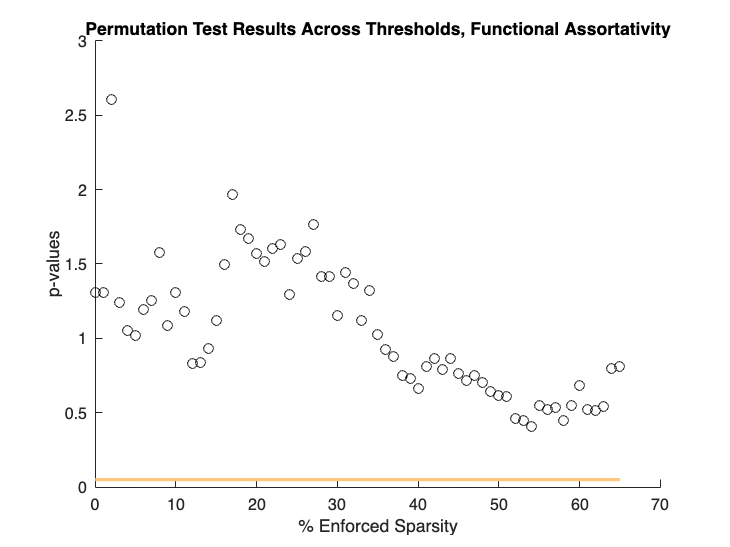

%functional assortativity
load('p_fc_glob_fdr.mat')
p_fc_a = p_fc_glob_fdr(1,:);
bT_fc_a = p_fc_a<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_a,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_a)*100,p_fc_a(bT_fc_a),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Assortativity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

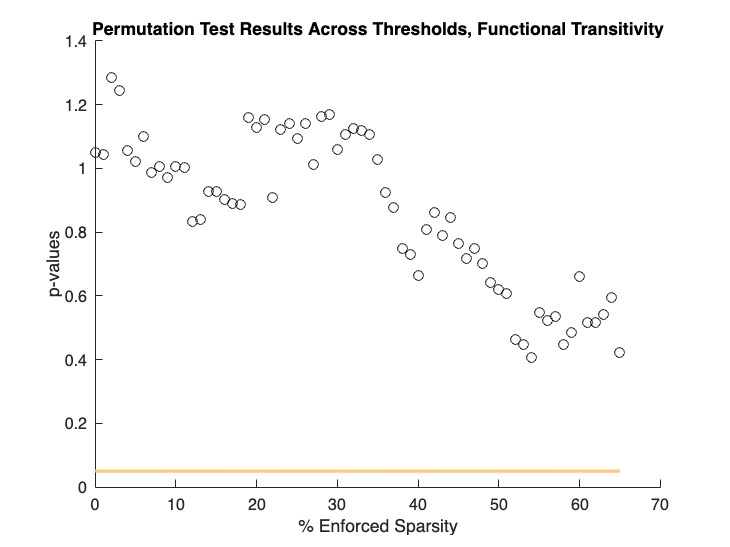

%functional transitivity
load('p_fc_glob_fdr.mat')
p_fc_trans = p_fc_glob_fdr(2,:);
bT_fc_trans = p_fc_trans<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_trans,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_trans)*100,p_fc_trans(bT_fc_trans),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Transitivity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

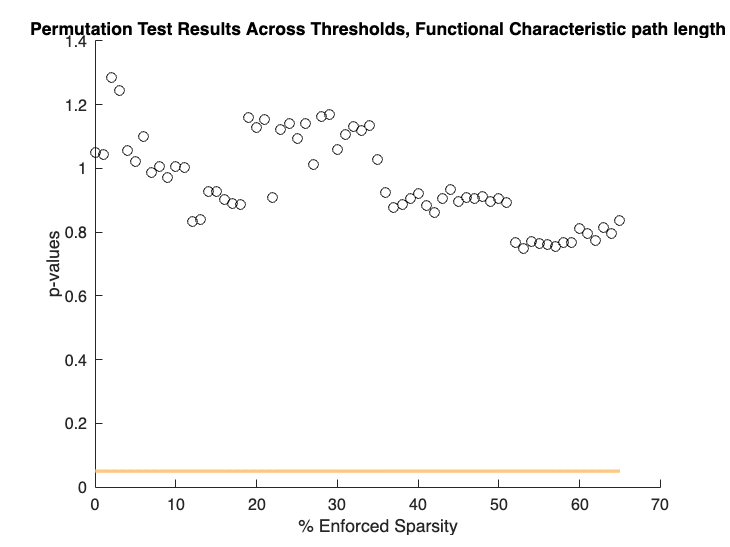

%functional Characteristic path length
load('p_fc_glob_fdr.mat')
p_fc_cp = p_fc_glob_fdr(3,:);
bT_fc_cp = p_fc_cp<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_cp,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_cp)*100,p_fc_cp(bT_fc_cp),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Characteristic path length')
ylabel('p-values')
xlabel('% Enforced Sparsity')

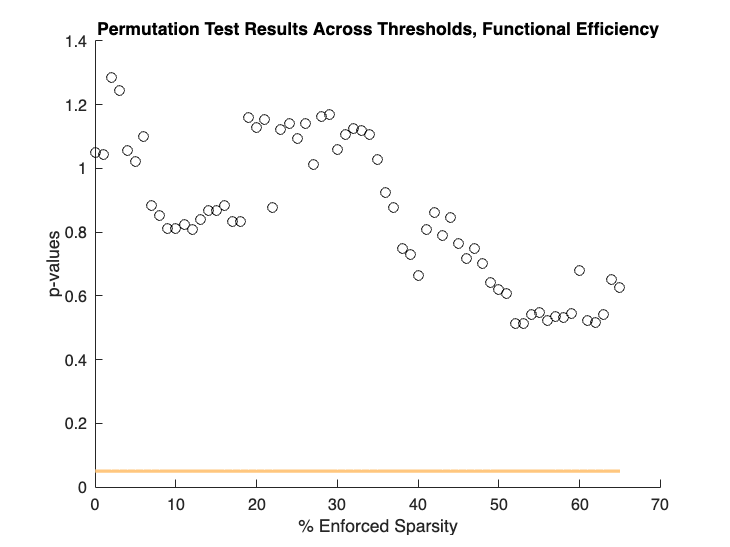

%functional Efficiency
load('p_fc_glob_fdr.mat')
p_fc_eff = p_fc_glob_fdr(4,:);
bT_fc_eff = p_fc_eff<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_eff,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_eff)*100,p_fc_eff(bT_fc_eff),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Efficiency')
ylabel('p-values')
xlabel('% Enforced Sparsity')

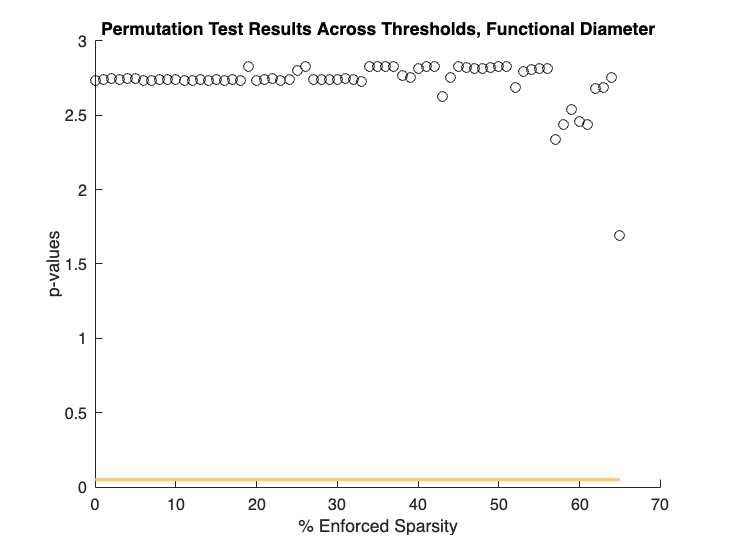

%functional Diameter
load('p_fc_glob_fdr.mat')
p_fc_diam = p_fc_glob_fdr(5,:);
bT_fc_diam = p_fc_diam<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_diam,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_diam)*100,p_fc_diam(bT_fc_diam),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Diameter')
ylabel('p-values')
xlabel('% Enforced Sparsity')

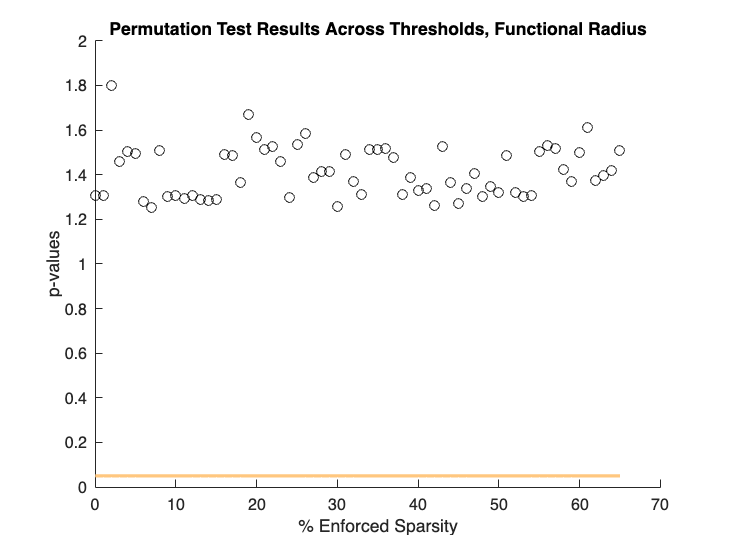

%functional Radius
load('p_fc_glob_fdr.mat')
p_fc_rad = p_fc_glob_fdr(6,:);
bT_fc_rad = p_fc_rad<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_rad,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_rad)*100,p_fc_rad(bT_fc_rad),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Radius')
ylabel('p-values')
xlabel('% Enforced Sparsity')

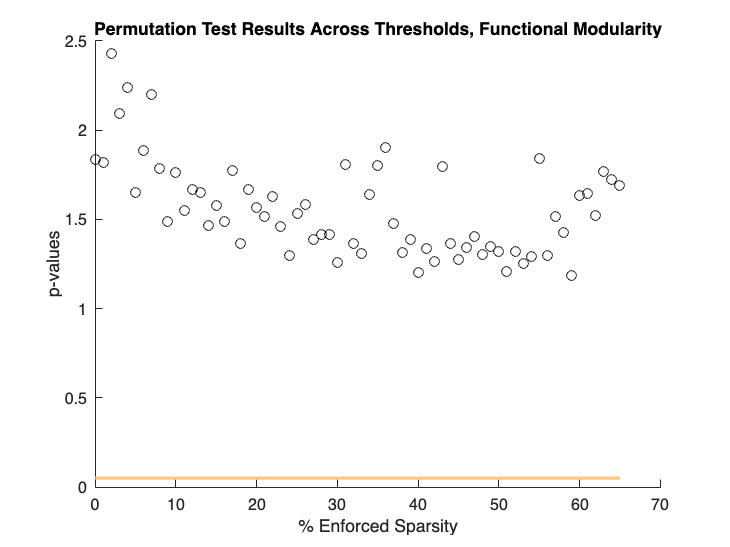

%functional Modularity
load('p_fc_glob_fdr.mat')
p_fc_mod = p_fc_glob_fdr(7,:);
bT_fc_mod = p_fc_mod<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_mod,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_mod)*100,p_fc_mod(bT_fc_mod),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Modularity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

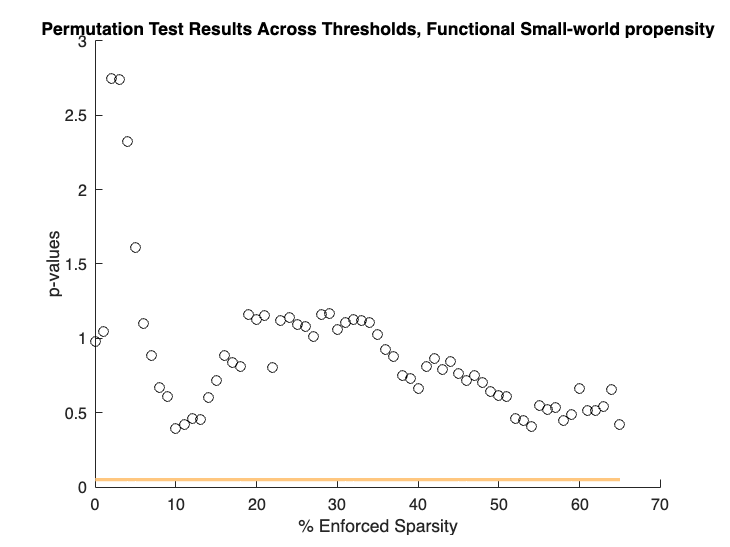

%functional Small-world propensity
load('p_fc_glob_fdr.mat')
p_fc_swp = p_fc_glob_fdr(8,:);
bT_fc_swp = p_fc_swp<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_swp,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_swp)*100,p_fc_swp(bT_fc_swp),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Small-world propensity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

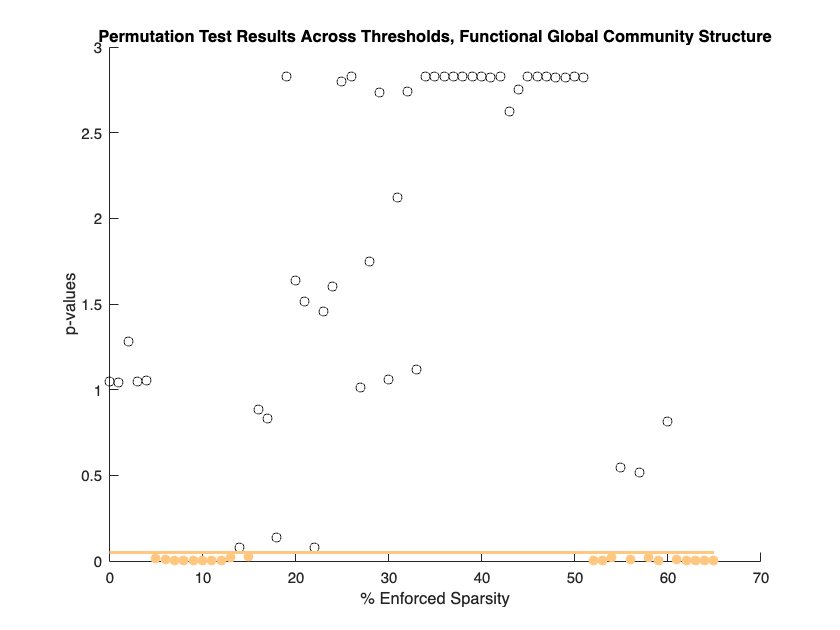

%functional Global community structure
load('p_fc_glob_fdr.mat')
p_fc_gcs = p_fc_glob_fdr(9,:);
bT_fc_gcs = p_fc_gcs<0.05;
figure;
hold on
scatter(consistency_fc*100,p_fc_gcs,'k')
p = plot(consistency_fc*100,0.05*ones(length(consistency_fc),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_fc(bT_fc_gcs)*100,p_fc_gcs(bT_fc_gcs),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Global Community Structure')
ylabel('p-values')
xlabel('% Enforced Sparsity')

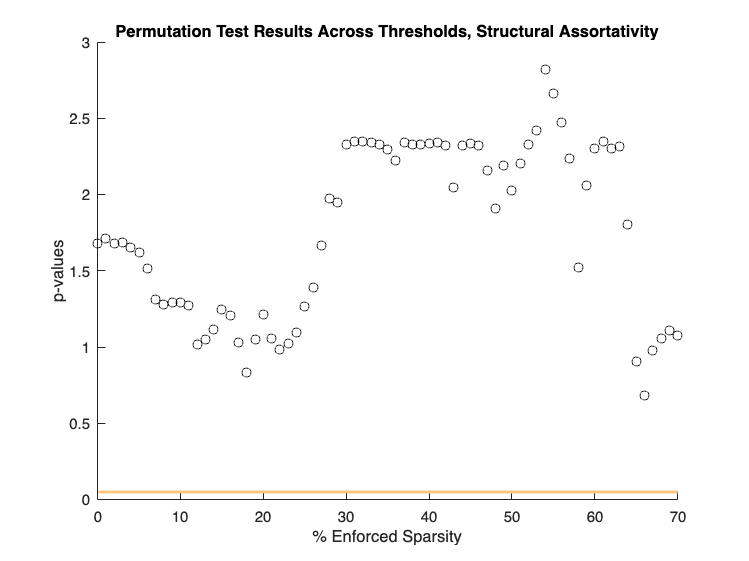

%Structural assortativity
load('p_w_glob_fdr.mat')
p_w_a = p_w_glob_fdr(1,:);
bT_w_a = p_w_a<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_a,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_a)*100,p_w_a(bT_w_a),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Assortativity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

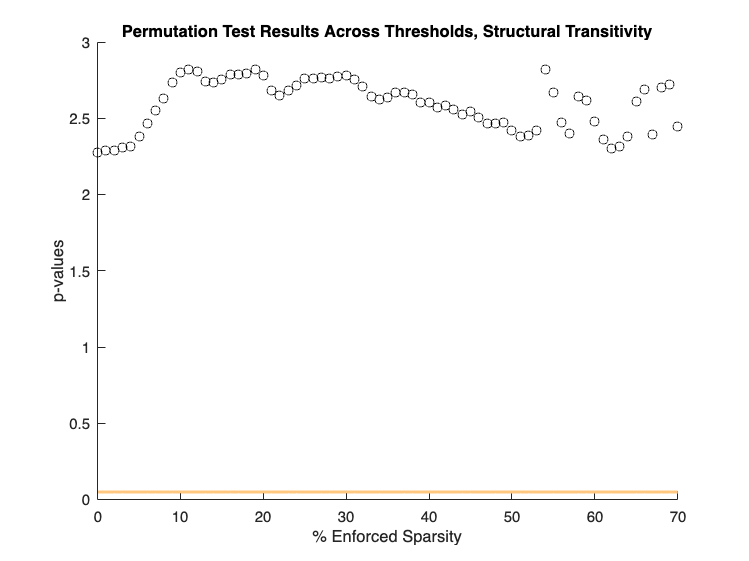

%Structural transitivity
load('p_w_glob_fdr.mat')
p_w_trans = p_w_glob_fdr(2,:);
bT_w_trans = p_w_trans<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_trans,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_trans)*100,p_w_trans(bT_w_trans),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Transitivity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

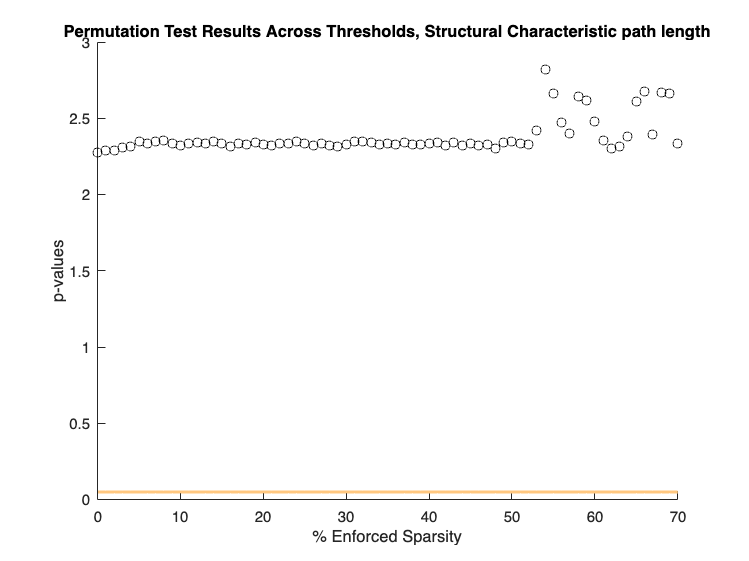

%Structural Characteristic path length
load('p_w_glob_fdr.mat')
p_w_cp = p_w_glob_fdr(3,:);
bT_w_cp = p_w_cp<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_cp,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_cp)*100,p_w_cp(bT_w_cp),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Characteristic path length')
ylabel('p-values')
xlabel('% Enforced Sparsity')

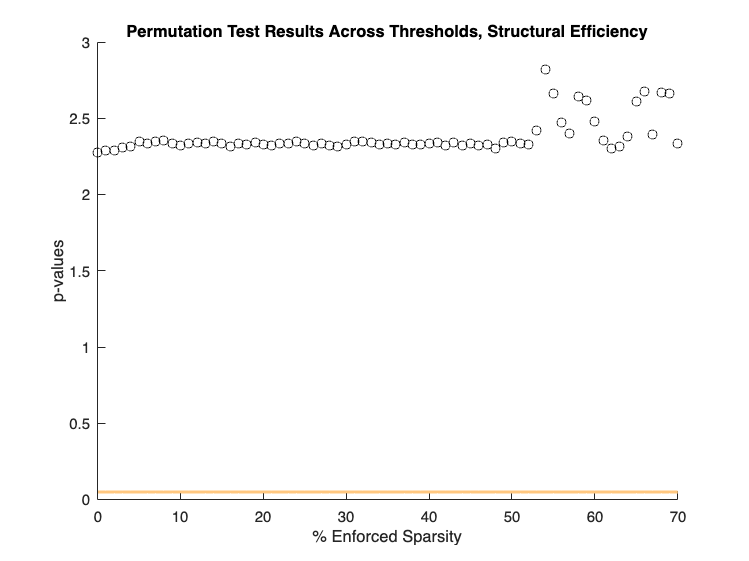

%Structural Efficiency
load('p_w_glob_fdr.mat')
p_w_eff = p_w_glob_fdr(4,:);
bT_w_eff = p_w_eff<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_eff,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_eff)*100,p_w_eff(bT_w_eff),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Efficiency')
ylabel('p-values')
xlabel('% Enforced Sparsity')

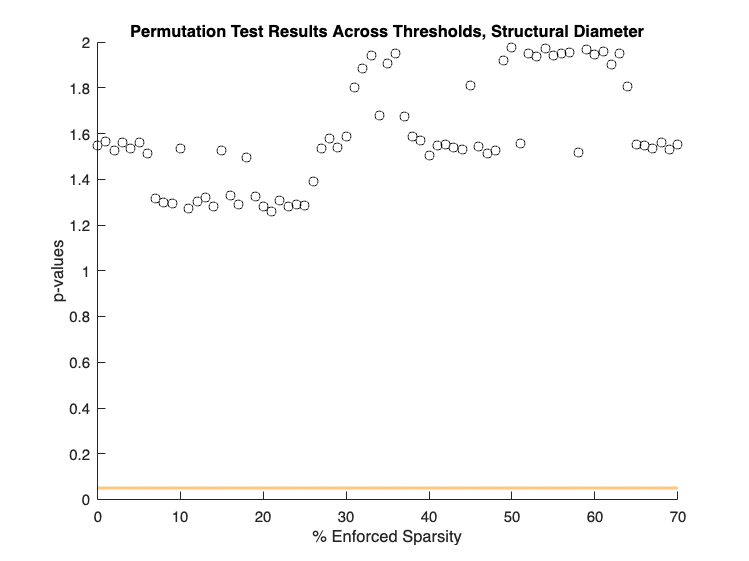

%Structural Diameter
load('p_w_glob_fdr.mat')
p_w_diam = p_w_glob_fdr(5,:);
bT_w_diam = p_w_diam<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_diam,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_diam)*100,p_w_diam(bT_w_diam),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Diameter')
ylabel('p-values')
xlabel('% Enforced Sparsity')

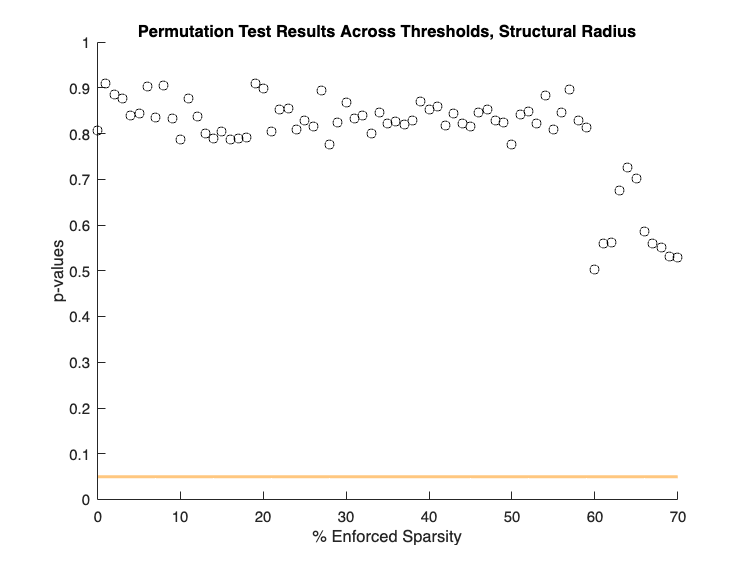

%Structural Radius
load('p_w_glob_fdr.mat')
p_w_rad = p_w_glob_fdr(6,:);
bT_w_rad = p_w_rad<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_rad,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_rad)*100,p_w_rad(bT_w_rad),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Radius')
ylabel('p-values')
xlabel('% Enforced Sparsity')

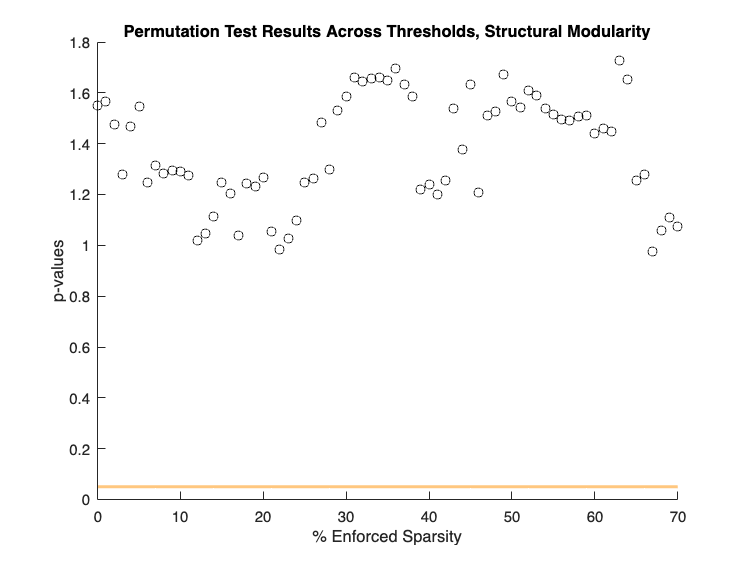

%Structural Modularity
load('p_w_glob_fdr.mat')
p_w_mod = p_w_glob_fdr(7,:);
bT_w_mod = p_w_mod<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_mod,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_mod)*100,p_w_mod(bT_w_mod),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Modularity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

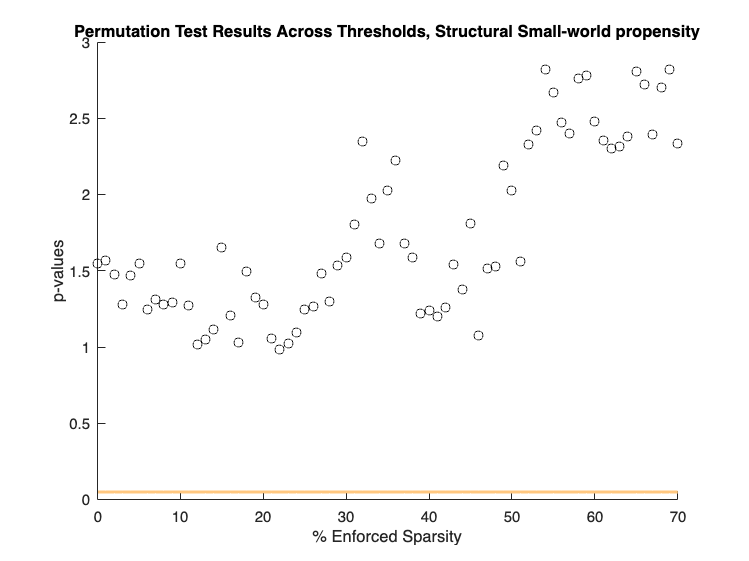

%Structural Small-world propensity
load('p_w_glob_fdr.mat')
p_w_swp = p_w_glob_fdr(8,:);
bT_w_swp = p_w_swp<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_swp,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_swp)*100,p_w_swp(bT_w_swp),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Small-world propensity')
ylabel('p-values')
xlabel('% Enforced Sparsity')

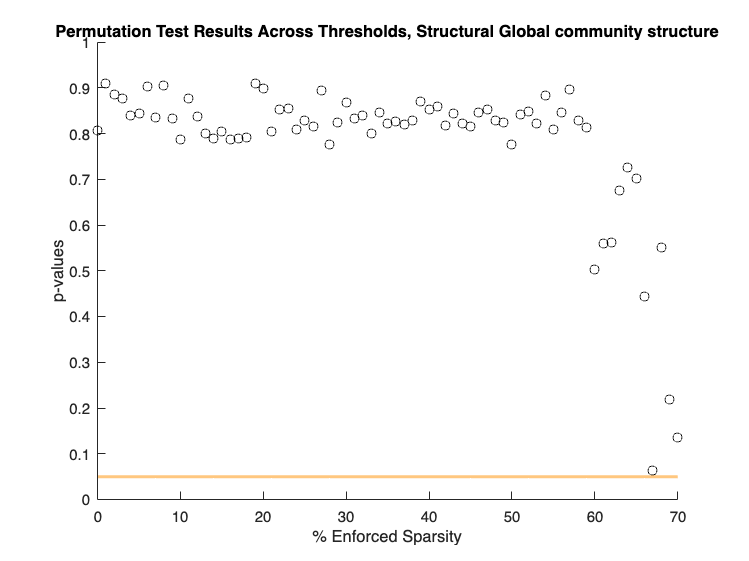

%Structural Global community structure
load('p_w_glob_fdr.mat')
p_w_gcs = p_w_glob_fdr(9,:);
bT_w_gcs = p_w_gcs<0.05;
figure;
hold on
scatter(consistency_w*100,p_w_gcs,'k')
p = plot(consistency_w*100,0.05*ones(length(consistency_w),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_w(bT_w_gcs)*100,p_w_gcs(bT_w_gcs),'o','filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Structural Global community structure')
ylabel('p-values')
xlabel('% Enforced Sparsity')

## Plotting Code General Formatting

c = copper;
first_color_rgb = c(1,:); % Dark brown
last_color_rgb = c(end,:); % Light brown

bT = pvalues<0.05;
figure;
imagesc(bT)
colormap('copper')
cbh = colorbar;
cbh.Ticks = [0,1];
cbh.TickLabels = ['p>0.05';'p<0.05'];
xlabel('% Enforced Sparsity of Matrix')
xticks([1,11,21,31,41,51,61,71])
xticklabels([0,10,20,30,40,50,60,70])
ylabel('Brain Regions')
title('Permutation Test Results Across Thresholds, Functional Betweenness Centrality')

bT = pvalues<0.05;
sum(bT)
figure;
hold on
scatter(consistency_range*100,pvalues,'k')
p = plot(consistency_range*100,0.05*ones(length(consistency_range),1));
p.Color = last_color_rgb;
p.LineWidth = 2;
s = scatter(consistency_range(bT)*100,pvalues(bT),'filled');
s.MarkerEdgeColor = last_color_rgb;
s.MarkerFaceColor = last_color_rgb;
hold off
title('Permutation Test Results Across Thresholds, Functional Assortativity')
ylabel('P-Values')
xlabel('% Enforced Sparsity')